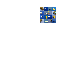

% Load Image Data
folderName = "MerchData";
unzip("MerchData.zip", folderName);

% Create an image datastore
imds = imageDatastore(folderName, ...
    IncludeSubfolders=true, ...
    LabelSource="foldernames");

% Display some sample images
numImages = numel(imds.Labels);
idx = randperm(numImages,16);
I = imtile(imds, Frames=idx);
figure
imshow(I)

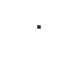


% Extract the class names and the number of classes
classNames = categories(imds.Labels);
numClasses = numel(classNames);

% Partition the data into training, validation, and testing datasets
[imdsTrain, imdsValidation, imdsTest] = splitEachLabel(imds, 0.7, 0.15, 0.15, "randomized");

deepNetworkDesigner

%specifying training options 
options = trainingOptions("adam", ...
    ValidationData=imdsValidation, ...
    ValidationFrequency=5, ...
    Plots="training-progress", ...
    Metrics="accuracy", ...
    Verbose=false);

%training neural network
net = trainnet(imdsTrain,net_1,"crossentropy",options);

%Testing network
inputSize = net.Layers(1).InputSize(1:2);

augimdsTrain = augmentedImageDatastore(inputSize,imdsTest);

YTest = minibatchpredict(net,imdsTest);
YTest = scores2label(YTest,classNames);

%visualise the classification
TTest = imdsTest.Labels;
figure
confusionchart(TTest,YTest);

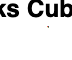


%classifying new image
im = imread("MerchDataTest.jpg");

im = imresize(im,inputSize(1:2));
X = single(im);
scores = predict(net,X);
[label,score] = scores2label(scores,classNames);
figure
imshow(im)
title(string(label) + " (Score: " + gather(score) + ")")